# Model Predictive Control - Exam Assignment 2021

clear all; close all; clc;
addpath('Functions\')
addpath('Functions\Realization\')

## Initialization

Gamma1 = 0.6; Gamma2 = 0.75; % Minimum Phase System
% Gamma1 = 0.45; Gamma2 = 0.4; % Non-Minimum Phase System

[p,a,A,g,rho] = get_parameters(Gamma1,Gamma2); 
[t0,t_f,Ts,t,T_plot,N,F1,F2,F3,F4,x0,u,d,u_rep,d_rep] = get_simulationScenario();

u1 = 1.10*u_rep;  u2 = 1.25*u_rep;   u3 = 1.50*u_rep;

% Steady states
xs0 = 5000*ones(4,1);       % Initial guess of steady state
us  = u;
xs  = fsolve(@ModifiedFourTankSystemWrap, xs0, [], u ,d , p); % Steady State


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ys  = FourTankSystemSensor(xs,p); % Get outputs
zs  = FourTankSystemOutput(xs,p); % Get measured outputs

% x0 = xs;

## Problem 4.1

[Ac,Bc,Cc,Cz,Ec] = get_linearizedModel(p,xs)

Ac =    -0.0152         0    0.0518         0
         0   -0.0113         0    0.0324
         0         0   -0.0518         0
         0         0         0   -0.0324


Bc =     0.6000         0
         0    0.7500
         0    0.2500
    0.4000         0


Cc =     0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026


Cz =     0.0026         0         0         0
         0    0.0026         0         0


Ec =      0     0
     0     0
     1     0
     0     1



% % For the SDE system
% Gc = diag([2^2 2^2 2^2 2^2]);
% [Acnew,Bcnew,Qcnew] = c2dzohsw(Ac,Bc,Gc,Ts) % Note that this is discrete time??

Check Lecture 2 and the book in lecture 2 for STDs

## Problem 4.2

sys = ss(Ac,Bc,Cc,0);
sys_pole = pole(sys)

sys_pole =    -0.0152
   -0.0113
   -0.0518
   -0.0324


sys_zero = tzero(sys)


sys_zero =

  0×1 empty double column vector



sys_eig = eig(Ac)

sys_eig =    -0.0152
   -0.0113
   -0.0518
   -0.0324


sys_gain = dcgain(sys)

sys_gain =     0.1036    0.0431
    0.0934    0.1751
         0    0.0127
    0.0325         0



% From Lecture02
sys_M = [Ac Bc ; Cz zeros(2,2)]

sys_M =    -0.0152         0    0.0518         0    0.6000         0
         0   -0.0113         0    0.0324         0    0.7500
         0         0   -0.0518         0         0    0.2500
         0         0         0   -0.0324    0.4000         0
    0.0026         0         0         0         0         0
         0    0.0026         0         0         0         0


sys_N = [eye(4,4) zeros(4,2) ; zeros(2,4) zeros(2,2)]

sys_N =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


sys_z = eig(sys_M,sys_N)

sys_z =        Inf
   -0.0205
   -0.0637
       Inf
       Inf
       Inf


## Problem 4.3

G = tf(sys)

G =
 
  From input 1 to output...
        0.001578
   1:  -----------
       s + 0.01524
 
                3.408e-05
   2:  ---------------------------
       s^2 + 0.04365 s + 0.0003649
 
   3:  0
 
        0.001052
   4:  -----------
       s + 0.03239
 
  From input 2 to output...
                3.408e-05
   1:  ---------------------------
       s^2 + 0.06706 s + 0.0007898
 
        0.001973
   2:  -----------
       s + 0.01127
 
        0.0006577
   3:  -----------
       s + 0.05182
 
   4:  0
 
Continuous-time transfer function.



## Problem 4.4

Just compare the gains obtained in 3.4 to the gains obtained in 4.3

## Problem 4.5

[Ad,Bd]=c2dzoh(Ac,Bc,Ts)

Ad =     0.9409         0    0.1814         0
         0    0.9559         0    0.1188
         0         0    0.8128         0
         0         0         0    0.8785


Bd =     2.3283    0.0949
    0.0978    2.9334
         0    0.9032
    1.5007         0


[~,Ed]=c2dzoh(Ac,Ec,Ts)

Ed =     0.3795         0
         0    0.2445
    3.6127         0
         0    3.7517


Cd = Cc

Cd =     0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026


Cdz = Cz

Cdz =     0.0026         0         0         0
         0    0.0026         0         0


## Problem 4.6

% k = 4;
% [H] = get_MarkovParameters(Ad,Bd,Cd,k);

sys_d = ss(Ad,Bd,Cd,0,Ts)

sys_d =
 
  A = 
           x1      x2      x3      x4
   x1  0.9409       0  0.1814       0
   x2       0  0.9559       0  0.1188
   x3       0       0  0.8128       0
   x4       0       0       0  0.8785
 
  B = 
            u1       u2
   x1    2.328  0.09487
   x2  0.09782    2.933
   x3        0   0.9032
   x4    1.501        0
 
  C = 
             x1        x2        x3        x4
   y1  0.002631         0         0         0
   y2         0  0.002631         0         0
   y3         0         0  0.002631         0
   y4         0         0         0  0.002631
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Sample time: 4 seconds
Discrete-time state-space model.



Gd = tf(sys_d)

Gd =
 
  From input 1 to output...
        0.006125
   1:  ----------
       z - 0.9409
 
       0.0002573 z + 0.0002428
   2:  -----------------------
       z^2 - 1.834 z + 0.8398
 
   3:  0
 
        0.003948
   4:  ----------
       z - 0.8785
 
  From input 2 to output...
       0.0002496 z + 0.0002282
   1:  -----------------------
       z^2 - 1.754 z + 0.7647
 
        0.007717
   2:  ----------
       z - 0.9559
 
        0.002376
   3:  ----------
       z - 0.8128
 
   4:  0
 
Sample time: 4 seconds
Discrete-time transfer function.



Ts = 4;
Nmax = 300;
tol = 1.0e-8;
Dd = zeros(2,2)

Dd =      0     0
     0     0


H = mimodss2dimpulse(Ad,Bd,Cz,Dd,Nmax)

H = H(:,:,1) =

     0     0
     0     0


H(:,:,2) =

    0.0061    0.0002
    0.0003    0.0077


H(:,:,3) =

    0.0058    0.0007
    0.0007    0.0074


H(:,:,4) =

    0.0054    0.0010
    0.0011    0.0071


H(:,:,5) =

    0.0051    0.0012
    0.0014    0.0067


H(:,:,6) =

    0.0048    0.0014
    0.0017    0.0064


H(:,:,7) =

    0.0045    0.0015
    0.0019    0.0062


H(:,:,8) =

    0.0042    0.0015
    0.0020    0.0059


H(:,:,9) =

    0.0040    0.0016
    0.0022    0.0056


H(:,:,10) =

    0.0038    0.0016
    0.0023    0.0054


H(:,:,11) =

    0.0035    0.0016
    0.0023    0.0051


H(:,:,12) =

    0.0033    0.0015
    0.0024    0.0049


H(:,:,13) =

    0.0031    0.0015
    0.0024    0.0047


H(:,:,14) =

    0.0029    0.0015
    0.0024    0.0045


H(:,:,15) =

    0.0028    0.0014
    0.0024    0.0043


H(:,:,16) =

    0.0026    0.0014
    0.0024    0.0041


H(:,:,17) =

    0.0025    0.0013
    0.0023    0.0039


H(:,:,18) =

    0.0023    0.0012
    0.0023    0.00

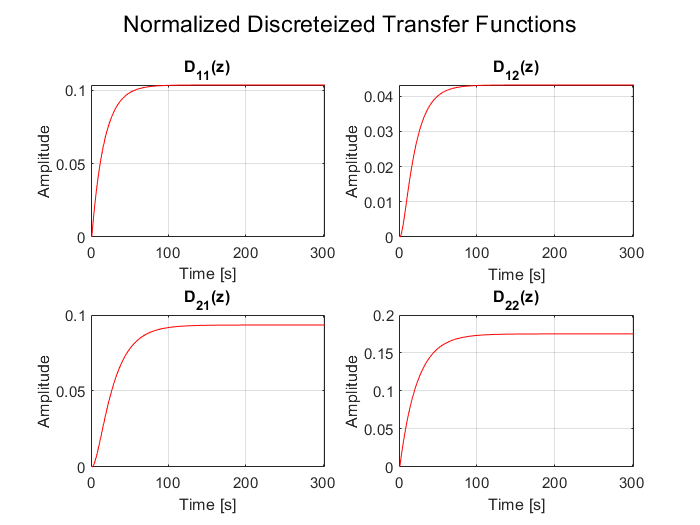

j = 1

j = 2

j = 1

j = 2

S = mimodss2dstep(Ad,Bd,Cz,Dd,N);        % Step response of approximate state space model
p = 2;          % number of outputs
m = 2;          % number of inputs 
figure(1)                                 % Plot the results (blue = exact, red = approx.)
sgtitle('Normalized Discreteized Transfer Functions')
  s1= zeros(N+1,1);
for i=1:m
    for j=1:p
        for k=1:N+1
      
            s1(k) = S(j,i,k);
       
        end
        j
        subplot(p,m,(j-1)*m+i)
%         hold on;
        plot(s1,'r-');grid on;
        xlabel('Time [s]')
        ylabel('Amplitude')
        title("D_{" + j + i + "}(z)")
%         hold off
    end

end

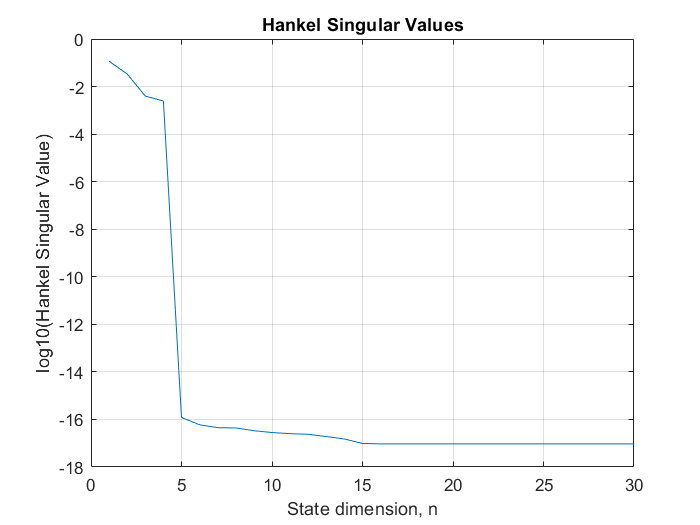

[pp,mm,Np1]=size(H);
NN = floor((Np1-1)/2);

HH = zeros(pp*(NN+1),mm*NN);
for i=1:NN;
    kc1 = (i-1)*mm+1;
    kc2 = kc1+mm-1;
    for j=1:NN+1;
        kr1 = 1 + (j-1)*pp;
        kr2 = kr1 + pp - 1;
        HH(kr1:kr2,kc1:kc2) = H(:,:,2+(i-1)+(j-1));
    end
end
% SVD of the Hankel Matrix
[K,S,L] = svd(HH(1:pp*NN,1:mm*NN));
% Select the state dimension
sH = diag(S);

% [Ad1,Bd1,Cd1,Dd1,sH1]=mimoctf2dss(num,den,tau,Ts,Nmax,tol);
% Markov Parameters
figure;
plot(log10(sH));grid on;
title('Hankel Singular Values')
xlabel('State dimension, n');xlim([0 30])
ylabel('log10(Hankel Singular Value)')

## Problem 4.7

Discussion and comment on linearization.

## Problem 5.1

Just add linear discrete time representation in overleaf

## Problem 5.2

[Qe,Rv,W,V,Qe_bar,W_bar,Gd_bar] = get_noise(N,Ed) % Get noise for the stochastic system

Qe =     25     0
     0    25


Rv =      4     0     0     0
     0     4     0     0
     0     0     4     0
     0     0     0     4


W =     7.6934    2.1509   -2.1904    0.5066    5.0146   -2.5314   -7.0292   -5.1688    3.5915   -2.5488   -3.1506   -3.7458    1.5621   -3.3950   -0.6481    5.3873    7.5052   -0.4956   -1.2650   -2.2502   -3.7723    5.2801    8.0078   -3.4095    6.5149    0.8836   -7.7003   -8.5105    2.8965    1.8331    1.1152   -2.8775   -7.5419    4.1066    4.3125   -1.3897   -8.5497   -8.1616    0.5891    4.7760   -2.8098   -0.3568   -3.1179   -6.1252    5.9244   -1.2013    2.4100   -4.3072   -5.4715    3.1116
    2.7352    3.6928   -8.5620   -1.6643   -3.1108    1.1106   -1.6446   -2.4339    4.8436   -3.9047   -5.7681   -0.0624   -6.0813    1.0401    6.2371    3.7254   -4.0751  -10.7582    1.0345    3.7947   -6.2434   -6.4693   -3.8117    2.5346    1.1126    8.7697   -8.2482   -7.6741   -1.3261   -3.4744    3.5510   -0.3797   -4.3078    3.1318    6.0476   -5.2155    0.7506    1.7584    0.8197   -3.6192   -9.0646   -3.3047    1.7907    1.5438    2.1232    3.4536   -3.2512    5.6354  -11.5957   -4

V =    -0.4736    3.8753   -0.1938    0.7564    0.6809    0.4613   -4.7516   -1.3093    3.2081    1.6590   -1.4029    3.0281    3.7647   -0.0983    0.3218    2.0565    1.9552   -0.0227    2.1159   -1.3325    0.5454    0.1343   -1.6547   -1.0448    4.1439   -2.1363    1.0404    2.5744   -0.3655    0.4108   -1.4766    0.7658   -3.1866   -0.5551   -0.1654   -0.3282    2.1459    0.3271    0.7891    0.4766   -1.1371    1.9380    2.6401   -1.9139    0.3238    0.5505   -0.3321   -0.8826    0.9953   -3.8873
   -3.7709   -1.0388   -1.3936    0.0396    1.4185    3.1586    0.1066   -3.1724   -1.0434    1.6280   -0.7952    1.6692   -2.3974   -0.9549    0.6269    0.5348    1.5631    0.6748    1.4754   -2.3285   -4.1057    0.7978   -2.3129    0.6354   -0.3274   -4.0939    1.0128   -0.9822   -2.1527   -0.9169   -0.0192   -3.9130   -1.3693   -1.1646    3.9005    3.3523    0.4800   -2.4454   -4.7943    2.9026    2.3996   -1.2494   -0.1166    0.2676    0.1644    0.6721    1.9596   -0.5923   -3.0757    1

Qe_bar =     3.5998         0         0         0
         0    1.4950         0         0
         0         0  326.2817         0
         0         0         0  351.8874


W_bar =     2.8151    2.4135    0.7635   -0.8870    1.3800   -0.4951   -1.3062    1.3155   -1.3776   -0.4325   -1.2445   -1.2171    0.4379   -0.5347    5.6404   -0.8155    1.3829    2.3292   -1.0608    0.8156   -1.5383    2.0038    1.1188    2.5661   -0.8670   -2.2320    0.8942    0.5971   -3.6733    0.2456   -2.9377    3.7935    0.0736    0.2837    2.5734    2.2040   -0.5544   -0.0100   -1.1412    2.5964   -3.2133    1.8215   -0.9559    0.2469   -0.4703   -2.3214    3.2626   -0.6457   -0.6100   -1.5229
    1.4709   -0.2730   -0.6744   -0.0022    1.9490    0.3090    0.8589    0.0342    0.1122    1.6376   -0.2185    2.0429    0.4745    0.2340   -0.1361   -2.0118    3.0023    0.0545   -0.0377    0.3215   -1.1853   -1.8416   -0.7908    1.6632   -0.8554    1.7381   -0.4525    2.3792   -0.0155   -0.7060   -0.8027    0.1027   -0.5276    0.1210   -0.5713    0.1424    0.5078    0.4169   -1.0856    0.5270    1.7276   -0.4646   -0.2903   -1.2716    1.5044   -1.9380   -0.9142   -1.8248    0.4085 

Gd_bar =     25     0     0     0
     0    25     0     0
     0     0    25     0
     0     0     0    25


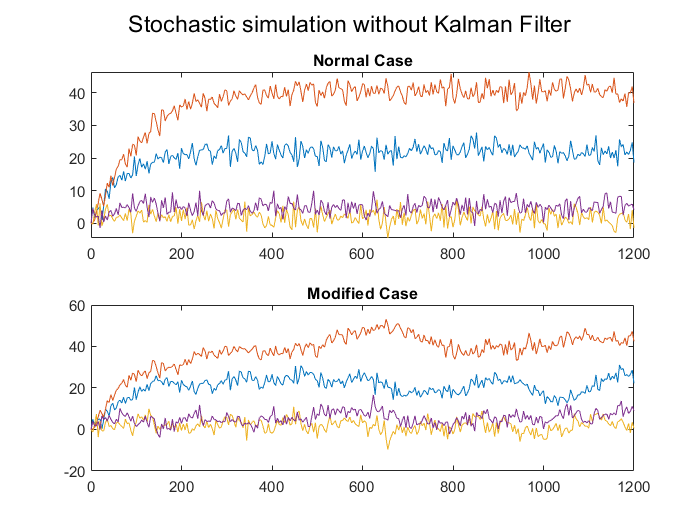


% Stochastic Simulation, normal and modified case
x_sim = zeros(4,N);
u_sim = u_rep;
y_sim = zeros(4,N);

x_sim(:,1) = x0 - xs;    % This will become -xs inly in the beginning, zeros everywhere else
u_sim = u_sim - us;      % This will become zeros because u_sim = 300 and us = 300
y_sim = y_sim - ys;      % This will become -ys everywhere

% Simulation for normal case
for k=1:N-1
    x_sim(:,k+1) = Ad*x_sim(:,k)  + Bd*u_sim(:,k) + Ed*(d_rep(:,k) + W(:,k));
    y_sim(:,k+1) = Cd*x_sim(:,k+1) + V(:,k+1); 
end

xbar_sim = x_sim; % Simulation with W_bar
ybar_sim = y_sim; % Simulation with W_bar

% Simulation for modified case
for k=1:N-1
    xbar_sim(:,k+1) = Ad*xbar_sim(:,k)  + Bd*u_sim(:,k) + Ed*d_rep(:,k) + Gd_bar*W_bar(:,k);
    ybar_sim(:,k+1) = Cd*xbar_sim(:,k+1) + V(:,k+1); 
end

y_sim    = y_sim'    + ys';
ybar_sim = ybar_sim' + ys';

figure;
% We can see that the state values go to xs or the steady states.
% xs
sgtitle('Stochastic simulation without Kalman Filter')
subplot(2,1,1)
plot(T_plot,y_sim,'DisplayName','Normal Stochastic Simulation'); 
title('Normal Case');
xlim([0 1200]);

% you can notice that the modified stochastic case has almost the same
% performance as the normal case.
subplot(2,1,2)
plot(T_plot,ybar_sim,'DisplayName','Modified Stochastic Simulation');
title('Modified Case');
xlim([0 1200]);

% % Static Kalman Filter
% [y_stochastic,y_est,~,~,KK_f,PP_cov,RR_e] = KalmanFilterStatic(x0,xs,ys,us,N,u_rep,Ad,Bd,Ed,Cd,W,d_rep,V,Qe_bar,Gd_bar,Rv);
% 
% figure;
% plot(T_plot,y_stochastic)
% hold on;
% plot(T_plot,y_est,'LineWidth',2.5)
% xlim([0 1200])
% title('Stochastic simulation with static Kalman Filter')
% xlabel('Time [s]'); ylabel('Magnitude')
% hold off;

% Dynamic Kalman Filter
[y_stochastic1,y_est1] = KalmanFilterDynamic(x0,xs,ys,us,N,u_rep,Ad,Bd,Ed,Cd,W,d_rep,V,Qe_bar,Gd_bar,Rv);

P_d = 	1.0e+-3 *

    0.2250         0         0         0
         0    0.2250         0         0
         0         0    0.2250         0
         0         0         0    0.2250


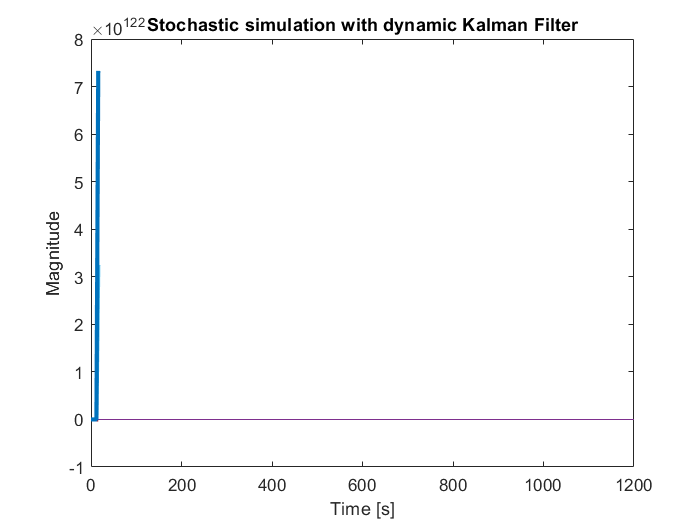


% y_stochastic = y_stochastic(1:2,:)' + ys(1:2)';
% y_est = y_est(1:2,:)' + ys(1:2)';
% % x_est = x_est';

figure;
plot(T_plot,y_stochastic1)
hold on;
plot(T_plot,y_est1,'LineWidth',2.5)
xlim([0 1200])
title('Stochastic simulation with dynamic Kalman Filter')
xlabel('Time [s]'); ylabel('Magnitude')
hold off;

## Problem 5.3

Steps in the disturbance d = [F3 ; F4]

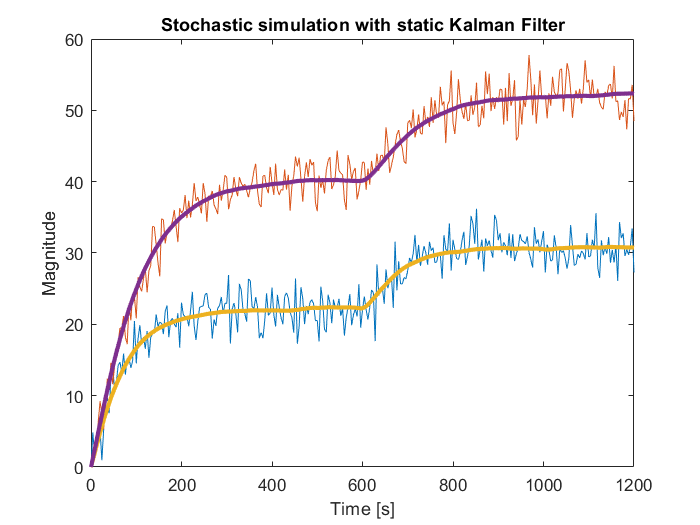

% Static Kalman Filter
[y_stochastic,y_est,K_f] = KalmanFilterStaticStep(x0,xs,ys,us,N,u_rep,Ad,Bd,Ed,Cd,W,d_rep,V,Qe_bar,Gd_bar,Rv);

figure;
plot(T_plot,y_stochastic)
hold on;
plot(T_plot,y_est,'LineWidth',2.5)
xlim([0 1200])
title('Stochastic simulation with static Kalman Filter')
xlabel('Time [s]'); ylabel('Magnitude')
hold off;

% % Dynamic Kalman Filter
% [y_stochastic2,y_est2] = KalmanFilterDynamicStep(x0,xs,ys,us,N,u_rep,Ad,Bd,Ed,Cd,W,d_rep,V,Qe_bar,Gd_bar,Rv);
% 
% figure;
% plot(T_plot,y_stochastic2)
% hold on;
% plot(T_plot,y_est2,'LineWidth',2.5)
% xlim([0 1200])
% title('Stochastic simulation with dynamic Kalman Filter')
% xlabel('Time [s]'); ylabel('Magnitude')
% hold off;

### Euler function from lecture03Empc

% function [T,X] = ImplicitEulerFixedStepSize(funJac,ta,tb,N,xa,varargin)
% 
% % Compute step size and allocate memory
% dt = (tb-ta)/N;
% nx = size(xa,1);
% X = zeros(nx,N+1);
% T = zeros(1,N+1);
% 
% tol = 1.0e-8;
% maxit = 100;
% 
% % Eulers Implicit Method
% T(:,1) = ta;
% X(:,1) = xa;
% for k=1:N
%     f = feval(fun,T(k),X(:,k),vararginf:g);
%     T(:,k+1) = T(:,k) + dt;
%     xinit = X(:,k) + dt*f;
%     X(:,k+1) = NewtonsMethodODE(funJac,...
%     T(:,k), X(:,k), dt, xinit, tol, maxit, ,vararginf:g));
% end
% 
% % Form a nice table for the result
% T = T';
% X = X';